Zadanie 1 - Transformata Laplace'a

syms t s A B C
A = 1; B = 1; C = A + B;

f1 = A * t * exp(-B * t);
f2 = A - exp(-2*t)*(sin(t-B) - cos(t-B) + sin(t-C)*cos(t-C));

L_f1 = laplace(f1);
L_f2 = laplace(f2);
disp('Obliczona transformata f1 Laplace');

Obliczona transformata f1 Laplace


disp(simplify(L_f1));

$$\frac{1}{{\left(s+1\right)}^{2}}$$

disp('Obliczona transformata f2 Laplace');

Obliczona transformata f2 Laplace


disp(simplify(L_f2));

$$\begin{array}{l} \sin\left(2\right)\,\left(\frac{2\,\sin\left(2\right)+\cos\left(2\right)\,\left(s+2\right)}{\sigma_{1}}+\frac{\cos\left(2\right)}{2\,\left(s+2\right)}\right)-\cos\left(2\right)\,\left(\frac{\sin\left(2\right)}{2\,\left(s+2\right)}+\frac{2\,\cos\left(2\right)-\sin\left(2\right)\,\left(s+2\right)}{\sigma_{1}}\right)+\frac{\sin\left(1\right)+\cos\left(1\right)\,\left(s+2\right)}{\sigma_{2}}-\frac{\cos\left(1\right)-\sin\left(1\right)\,\left(s+2\right)}{\sigma_{2}}+\frac{1}{s}\\ \mathrm{where}\\ \sigma_{1}=2\,\left({\left(s+2\right)}^{2}+4\right)\\ \sigma_{2}={\left(s+2\right)}^{2}+1 \end{array}$$

pretty(L_f1)

    1
--------
       2
(s + 1)



pretty(L_f2)

       / 2 sin(2) + cos(2) (s + 2)     cos(2)  \          /   sin(2)    2 cos(2) - sin(2) (s + 2) \   sin(1) + cos(1) (s + 2)   cos(1) - sin(1) (s + 2)   1
sin(2) | ------------------------- + --------- | - cos(2) | --------- + ------------------------- | + ----------------------- - ----------------------- + -
       \             #1              2 (s + 2) /          \ 2 (s + 2)               #1            /              #2                        #2             s

where

                 2
   #1 == ((s + 2)  + 4) 2

                2
   #2 == (s + 2)  + 1




Zadanie 2 - Transformata odwrotna Laplace'a

%ogólnie to śmieszna sprawa bo wykres tej transformaty raz działa raz nie działa 
F_s = (s^3 + 4*s^2 + 6*s + 5) / ((s+8) * (s^2 + 8*s + 3) * (s^2 + 5*s + 7));
f_t = ilaplace(F_s);
disp('Transformata Laplace');

Transformata Laplace


disp(F_s);

$$\frac{s^{3}+4\,s^{2}+6\,s+5}{\left(s+8\right)\,\left(s^{2}+8\,s+3\right)\,\left(s^{2}+5\,s+7\right)}$$

disp('Obliczona transformata odwrotna Laplace');

Obliczona transformata odwrotna Laplace


disp(f_t);

$$\frac{1367\,{\mathrm{e}}^{-4\,t}\,\left(\cosh\left(\sqrt{13}\,t\right)-\frac{4895\,\sqrt{13}\,\sinh\left(\sqrt{13}\,t\right)}{17771}\right)}{417}-\frac{272\,{\mathrm{e}}^{-\frac{5\,t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)+\frac{29\,\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{102}\right)}{4309}-\frac{299\,{\mathrm{e}}^{-8\,t}}{93}$$

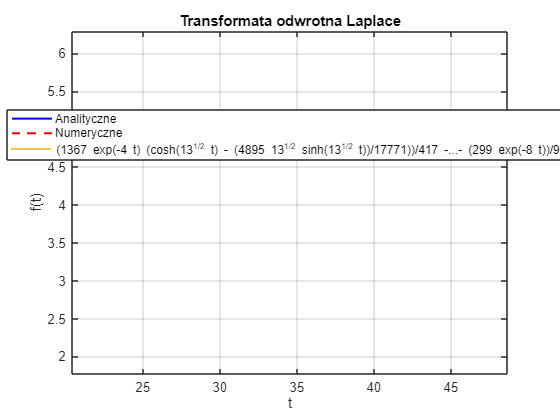


fplot(f_t, [0, 50]);
grid on;
title('Transformata odwrotna Laplace');
xlabel('t'); ylabel('f(t)');

Zadanie 3 - Rozwiązanie równania różniczkowego

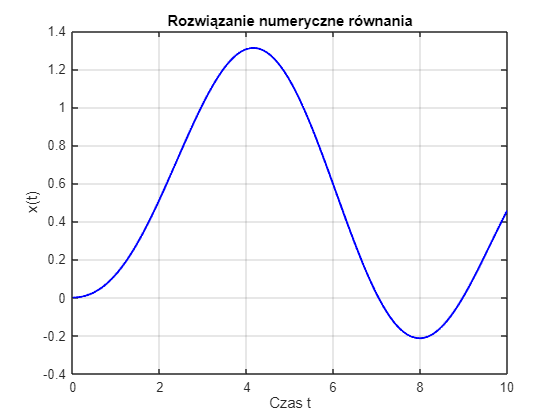

%a)-------------------------------------------------------------------------------------------
T_end = 10; % Czas końcowy symulacji
dt = 0.01; % Krok czasowy
t = 0:dt:T_end; % Wektor czasu

%b)-------------------------------------------------------------------------------------------
% Definiowanie układu równań pierwszego rzędu
ode_fun = @(t, x) [x(2); (-1/C * x(2) - 2*x(1) + A + sin(B*t)) / 5];

% Rozwiązanie równania dla zerowych wartości początkowych
x0 = [0; 0];
[T, X] = ode45(ode_fun, t, x0);

% Wykres rozwiązania (nie był w poleceniu, nie istotny jest)
figure;
plot(T, X(:,1), 'b', 'LineWidth', 1.5);
xlabel('Czas t');
ylabel('x(t)');
title('Rozwiązanie numeryczne równania');
grid on;

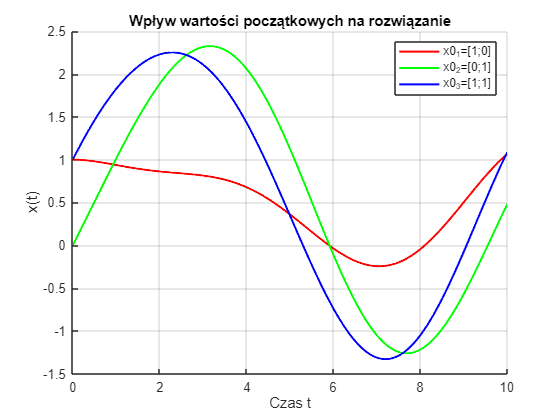


%c)-------------------------------------------------------------------------------------------
% "powtórzyć symulację dla co najmniej 3 różnych niezerowych wartości początkowych"
x0_1 = [1; 0];
x0_2 = [0; 1];
x0_3 = [1; 1];

[T1, X1] = ode45(ode_fun, t, x0_1);
[T2, X2] = ode45(ode_fun, t, x0_2);
[T3, X3] = ode45(ode_fun, t, x0_3);

figure;
hold on;
plot(T1, X1(:,1), 'r', 'LineWidth', 1.5);
plot(T2, X2(:,1), 'g', 'LineWidth', 1.5);
plot(T3, X3(:,1), 'b', 'LineWidth', 1.5);
xlabel('Czas t');
ylabel('x(t)');
title('Wpływ wartości początkowych na rozwiązanie');
legend('x0_1=[1;0]', 'x0_2=[0;1]', 'x0_3=[1;1]');
grid on;

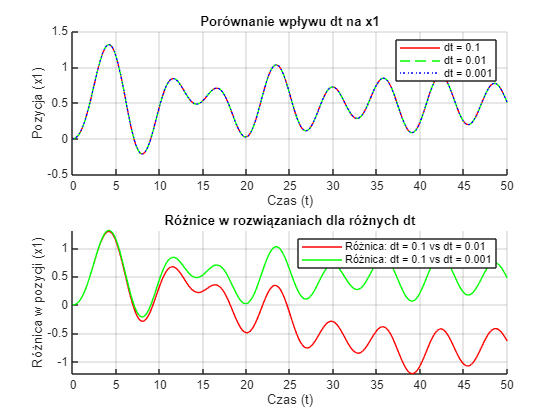


%d)-------------------------------------------------------------------------------------------
% testowanie delta t

%T_end
T_end = 50;

% Definicja funkcji ODE
ode_fun = @(t, x) [x(2); (-1/C * x(2) - 2*x(1) + A + sin(B*t)) / 5];

% Krok czasowy 1: dt = 0.1
dt = 0.1;
t = 0:dt:T_end;
x0 = [0; 0];
[T1, X1] = ode45(ode_fun, t, x0);

% Krok czasowy 2: dt = 0.01
dt = 0.01;
t = 0:dt:T_end;
x0 = [0; 0];
[T2, X2] = ode45(ode_fun, t, x0);

% Krok czasowy 3: dt = 0.001
dt = 0.001;
t = 0:dt:T_end;
x0 = [0; 0];
[T3, X3] = ode45(ode_fun, t, x0);

% Rysowanie wykresu dla x1
figure;
subplot(2,1,1); % Wykres dla x1
hold on;
plot(T1, X1(:,1), 'r-', 'DisplayName', 'dt = 0.1'); % Linia ciągła dla dt = 0.1
plot(T2, X2(:,1), 'g--', 'DisplayName', 'dt = 0.01'); % Linia przerywana dla dt = 0.01
plot(T3, X3(:,1), 'b:', 'DisplayName', 'dt = 0.001'); % Linia kropkowana dla dt = 0.001
hold off;
xlabel('Czas (t)');
ylabel('Pozycja (x1)');
title('Porównanie wpływu dt na x1');
legend show;
grid on;

% Rysowanie wykresu dla różnic między x1 dla różnych dt
subplot(2,1,2); % Wykres różnicowy dla x1
hold on;
plot(T1, X1(:,1) - X2(1:length(T1), 1), 'r-', 'DisplayName', 'Różnica: dt = 0.1 vs dt = 0.01');
plot(T1, X1(:,1) - X3(1:length(T1), 1), 'g-', 'DisplayName', 'Różnica: dt = 0.1 vs dt = 0.001');
hold off;
xlabel('Czas (t)');
ylabel('Różnica w pozycji (x1)');
title('Różnice w rozwiązaniach dla różnych dt');
legend show;
grid on;


%e)-------------------------------------------------------------------------------------------

%weryfikacja
num = [1 1]; % Licznik: s + 1
den = conv([1 0], conv([1 0 1], [5 1 2])); % Mianownik: s(s^2 + 1)(5s^2 + s + 2)

[r, p, k] = residue(num, den);

disp('Residua (liczniki ułamków prostych):');

Residua (liczniki ułamków prostych):


disp(r);

   0.1000 + 0.2000i
   0.1000 - 0.2000i
  -0.3500 - 0.2642i
  -0.3500 + 0.2642i
   0.5000 + 0.0000i



disp('Pierwiastki (mianowniki ułamków prostych):');

Pierwiastki (mianowniki ułamków prostych):


disp(p);

   0.0000 + 1.0000i
   0.0000 - 1.0000i
  -0.1000 + 0.6245i
  -0.1000 - 0.6245i
   0.0000 + 0.0000i



disp('Część całkowita:');

Część całkowita:


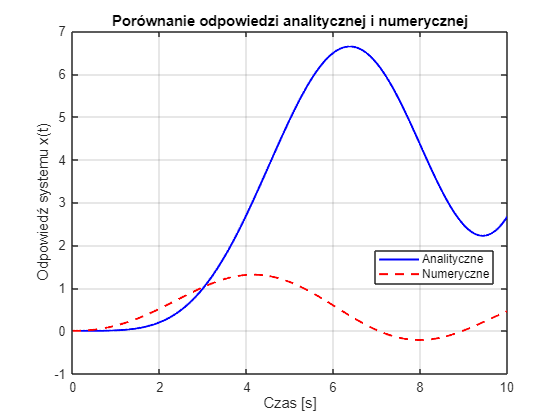

disp(k);

%f)-------------------------------------------------------------------------------------------
% Parametry
A = 1;       % Stała wymuszenia
B = 1;       % Częstotliwość sinusa
C = A + B;   % Stała związana z tłumieniem
T_end = 10;  % Czas symulacji
dt = 0.01;   % Krok czasowy
t = 0:dt:T_end; % Wektor czasu

% --- Rozwiązanie numeryczne ---
ode_fun = @(t, x) [x(2); (-1/C * x(2) - 2*x(1) + A + sin(B*t)) / 5];
x0 = [0; 0];
[T_num, X_num] = ode45(ode_fun, t, x0);
y_numerical = X_num(:, 1);  % x(t)

% --- Rozwiązanie analityczne ---
syms s
% 1. Definicja transmitancji Z(s) i wymuszenia U(s)
Z_s = (s + 1) / (s * (s^2 + 1) * (5*s^2 + s + 2)); % Definicja wyliczona analitycznie (jak człowiek pierwotny ręcznie)
U_s = A/s + B/(s^2 + B^2);  % Transformata Laplace'a wymuszenia A + sin(Bt)

% 2. Odpowiedź w dziedzinie Laplace'a: Y(s) = Z(s) * U(s)
Y_s = Z_s * U_s;

% 3. Obliczenie odwrotnej transformaty Laplace'a
y_analytical_t = ilaplace(Y_s);

% 4. Konwersja wyniku symbolicznego na funkcję numeryczną
y_analytical = double(subs(y_analytical_t, t));

% Usunięcie składowych urojonych (jeśli są pomijalne)
y_analytical = real(y_analytical);

% --- Wykres ---
figure;
plot(t, y_analytical, 'b', 'LineWidth', 1.5, 'DisplayName', 'Analityczne');
hold on;
plot(T_num, y_numerical, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Numeryczne');
xlabel('Czas [s]');
ylabel('Odpowiedź systemu x(t)');
title('Porównanie odpowiedzi analitycznej i numerycznej');
legend('Location', 'best');
grid on;